% Addestra un MLP (input→hidden→softmax) direttamente sui pixel dei volti,
% eliminando completamente la fase SVD.

clear; clc; close all;

%% Impostazioni path progetto
projectRoot = '/Users/giuseppebonomo/Desktop/UNIPA CdLM Ing_Informatica/.../ProgettoMetodi';
addpath(genpath(projectRoot));

%% Cartella risultati
results_path = fullfile(pwd,'results');
if ~exist(results_path,'dir')
    mkdir(results_path);
    fprintf('>>> Creo la cartella results\n');
end

%% 1) Caricamento dataset
fprintf('>>> Caricamento dataset...\n');

>>> Caricamento dataset...


tic;
load('dataset/volti_dataset.mat','A','labels');  % A (m×n), labels
A = double(A)/255;                               % normalizza [0,1]
[m, n] = size(A);
fprintf('   fatto in %.2f s\n', toc);

   fatto in 0.04 s



%% 2) Calcolo volto medio e centratura
fprintf('>>> Calcolo volto medio e centratura...\n');

>>> Calcolo volto medio e centratura...


tic;
mean_face   = mean(A,2);                 % [m×1]
save(fullfile(results_path,'mean_face.mat'),'mean_face');
A_centered  = A - mean_face;             % [m×n]
fprintf('   fatto in %.2f s\n', toc);

   fatto in 0.01 s



%% 3) Prepara X e y
X           = A_centered';               % [n_samples × m]
y           = labels(:);                 % [n_samples × 1]
num_classes = max(y);

%% 4) Split train/test (7 immagini per soggetto per train)
train_idx = []; test_idx = [];
for s = 1:num_classes
    idx = find(y==s);
    idx = idx(randperm(numel(idx)));
    train_idx = [train_idx; idx(1:7)];
    test_idx  = [test_idx;  idx(8:end)];
end

X_train = X(train_idx, :);  % [n_train × m]
y_train = y(train_idx);     % [n_train × 1]
X_test  = X(test_idx,  :);  % [n_test  × m]
y_test  = y(test_idx);      % [n_test  × 1]

%% 5) One-hot encoding
n_train = numel(y_train);
Y_train = zeros(num_classes, n_train);
for i = 1:n_train
    Y_train(y_train(i), i) = 1;
end

%% 6) Iperparametri MLP
hidden_size   = 128;
epochs        = 100;
learning_rate = 0.005;
dropout_rate  = 0.3;

%% 7) Training MLP (funzione invariata)
fprintf('>>> Training MLP via gradient descent...\n');

>>> Training MLP via gradient descent...


tic;
[W1,b1,W2,b2,loss_hist] = mlp_gradient_descent( ...
    X_train, Y_train, hidden_size, epochs, learning_rate, dropout_rate);

[Epoch  10/100] Loss = 3.5936
[Epoch  20/100] Loss = 3.4406
[Epoch  30/100] Loss = 3.3339
[Epoch  40/100] Loss = 3.2313
[Epoch  50/100] Loss = 3.1209
[Epoch  60/100] Loss = 3.0369
[Epoch  70/100] Loss = 2.9472
[Epoch  80/100] Loss = 2.8609
[Epoch  90/100] Loss = 2.7693
[Epoch 100/100] Loss = 2.7154


t_train = toc;
fprintf('   training completato in %.2f s\n', t_train);

   training completato in 4.76 s



%% 8) Valutazione sul test set
Z1     = W1 * X_test' + b1;     % [hidden_size × n_test]
A1     = max(0, Z1);            % ReLU
Z2     = W2 * A1 + b2;          % [num_classes × n_test]
Z2     = Z2 - max(Z2,[],1);     % stabilità numerica
expZ   = exp(Z2);
A2     = expZ ./ sum(expZ,1);   % softmax
[~, y_pred] = max(A2, [], 1);    % [1 × n_test]
y_pred = y_pred';                % [n_test × 1]

acc = mean(y_pred == y_test) * 100;
fprintf('Accuracy MLP (test set): %.2f%%\n', acc);

Accuracy MLP (test set): 60.16%


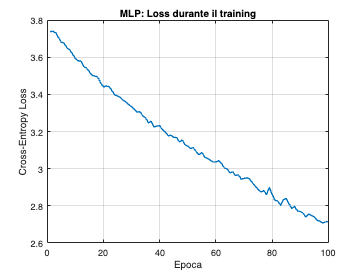


%% 9) Plot della loss
figure('Name','MLP: Cross-Entropy Loss','NumberTitle','off');
plot(1:epochs, loss_hist, 'LineWidth',1.5);
xlabel('Epoca'); ylabel('Cross-Entropy Loss');
title('MLP: Loss durante il training');
grid on;